## Stillbilder

clear
%image = double(imread('baboon.png'));
%image = double(imread('boat.png'));
image = double(imread('woodgrain.png'));

[x,y] = size(image);



p = distribution2d(image);
H1 = entropyOfDistribution(p)

H1 = 6.3562

#### Parentropi horisontellt


$$H\left(X_{i,j} ,X_{i+1,j} \right)$$



data = reshape(image,1,x*y);

horizontal_data = zeros(size(data));

horizontal_data(1,1) = data(1,1);
% Skiftar
for i = 2:size(data,2)
    horizontal_data(1,i) = data(1,i) - data(1,i-1);
end

% Tar bort negativa värden
horizontal_data = minshift(horizontal_data);

p2 = distribution2d(horizontal_data);
H_hori = entropyOfDistribution(p2)

H_hori = 4.4136

#### Parentropi vertikalt


$$H\left(X_{i,j} ,X_{i,j+1} \right)$$


% Transponera bilden ger vertikala grannar
data = reshape(image',1,x*y);
vertical_data = zeros(size(data));

vertical_data(1,1) = data(1,1);
% Skiftar
for i = 2:size(data,2)
    vertical_data(1,i) = data(1,i) - data(1,i-1);
end
% Tar bort negativa värden
vertical_data = minshift(vertical_data);

p3 = distribution2d(vertical_data);
H_vert = entropyOfDistribution(p3)

H_vert = 6.1877

#### Betingad


$$\left.H\left(X_{i+1,j} \right|X_{i,j} \right)$$


H_hori_cond = H_hori - H1

H_hori_cond = -1.9426

 H(Xi,j+1 | Xi,j) 

H_vert_cond = H_vert - H1

H_vert_cond = -0.1685

#### Huffmankodning


$$Y_{i,j} =X_{i,j} -P_{i,j}$$



l2 = huffman(p2)

l2 = 4.4531

l3 = huffman(p3)

l3 = 6.2102


data = padarray(image,[1 1],128, 'both');

pe1 = image;
%Horizontal
for x = 2:size(image,1) 
    for y = 2:size(image,2) 
        %newimage(x,y) = data(x,y) - (data(x-1,y) + data(x,y-1) - data(x-1,y-1));
        pe1(x,y) = pe1(x,y) - data(x-1,y);
    end
end

%Vertical
pe2 = image;
for x = 2:size(image,1) 
    for y = 2:size(image,2) 
        %newimage(x,y) = data(x,y) - (data(x-1,y) + data(x,y-1) - data(x-1,y-1));
        pe2(x,y) = pe2(x,y) - data(x,y-1);
    end
end

%Conditional
pe3 = image;
for x = 2:size(image,1) 
    for y = 2:size(image,2) 
        %newimage(x,y) = data(x,y) - (data(x-1,y) + data(x,y-1) - data(x-1,y-1));
        pe3(x,y) = pe3(x,y) - (data(x-1,y) + data(x,y-1) - data(x-1,y-1));
    end
end

l = huffman(p)

l = 6.3914

H1 = entropyOfDistribution(p)

H1 = 6.3562


%prediction_error = prediction_error(2:end-1,2:end-1);
%prediction_error = minshift(prediction_error);
[row,col] = size(pe1);
data_l4_h = reshape(pe1,row*col,1);
p4_h = distribution2d(data_l4_h);
l4_h = huffman(p4_h)

l4_h = 3.6308

H_hori = entropyOfDistribution(p4_h)

H_hori = 3.6161


[row,col] = size(pe2);
data_l4_v = reshape(pe2,row*col,1);
p4_v = distribution2d(data_l4_v);
l4_v = huffman(p4_v)

l4_v = 3.8371

H_vert = entropyOfDistribution(p4_v)

H_vert = 3.8185


[row,col] = size(pe3);
data_l4_c = reshape(pe3,row*col,1);
p4_c = distribution2d(data_l4_c);
l4_c = huffman(p4_c)

l4_c = 3.6277

H_cond = entropyOfDistribution(p4_c)

H_cond = 3.6107

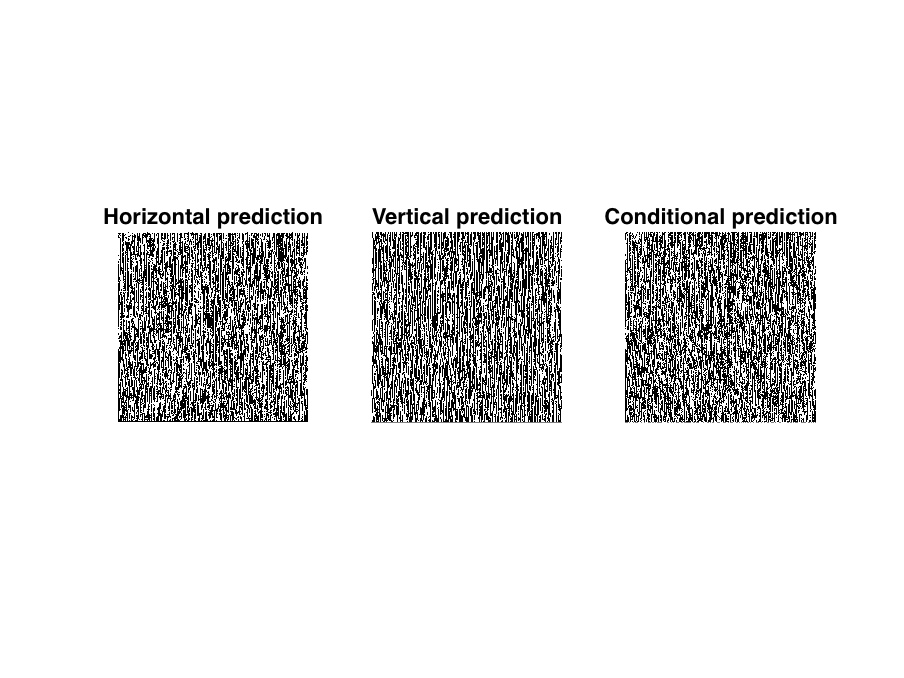



figure;
subplot(1,3,1);
imshow(pe1)
txt1 = ['Bitrate: ' num2str(l4_h)];
title('Horizontal prediction');
subtitle(txt1)

subplot(1,3,2);
imshow(pe2)
title('Vertical prediction');
txt2 = ['Bitrate: ' num2str(l4_v)];
subtitle(txt2)

subplot(1,3,3);
imshow(pe3)
title('Conditional prediction');
txt3 = ['Bitrate: ' num2str(l4_c)];
subtitle(txt3)